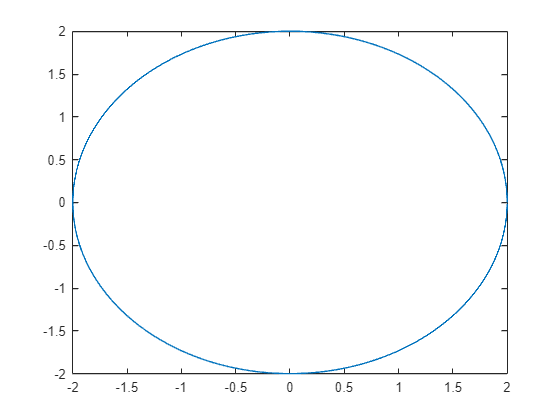

%Primer ejercicio
clear all
clc

t1=[-pi:0.025:pi];

x1=-2*cos(t1);
y1=-2*sin(t1);

plot(x1,y1);

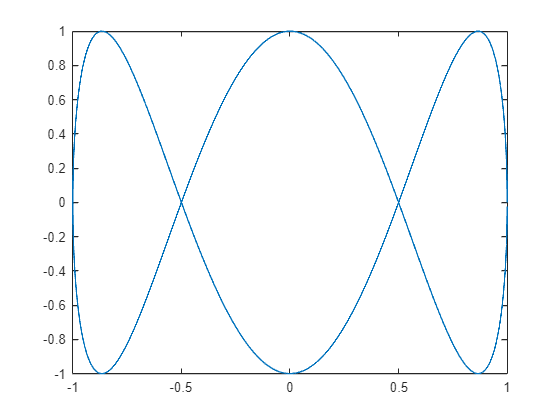


%Segundo ejercicio
t2=[-2*pi:0.025:2*pi];

x2=-cos(0.5*t2);
y2=-sin(1.5*t2);

plot(x2,y2);

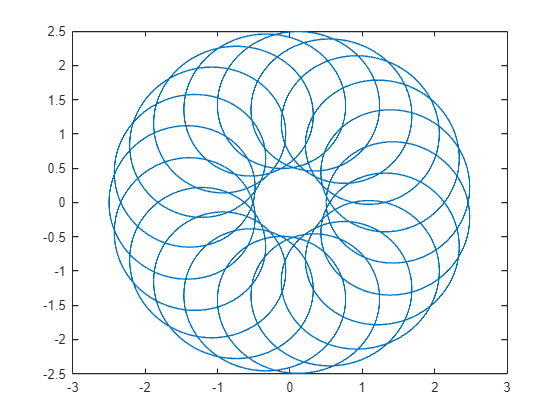

%Tercer ejercicio
t3=[-10*pi:0.025:10*pi];

x3=-1.5*cos(0.1*t3)-cos(2*t3);
y3=-1.5*sin(0.1*t3)-sin(2*t3);

plot(x3,y3);
% Parametros para el for
syms t

vec_x=[2*t  ,t-3*sin(t)  ,3*cos(t)-cos(3*t)  ,cos(t)+1/2*cos(7*t)+1/3*sin(17*t)  ,17*cos(t)+7*cos(17+7*t)  ,2*cos(t)  ,5*t-4*sin(t)  ,4*cos(t)+cos(4*t)  ,sin(2*t)  ,sin(4*t)];
vec_y=[(t-3*t)/3  ,4-3*cos(t)  ,4*sin(3*t)  , sin(t)+1/2*sin(7*t)+1/3*cos(17*t)  , 17*sin(t)-7*sin(17*t)  ,2*sin(t)  ,5-4*cos(t)  ,4*sin(t)-sin(4*t)  ,sin(3*t)  ,sin(5*t)];
vec_ti=[-2  ,0  ,0  ,0  ,0  ,0  ,-2*pi  ,0  ,0  ,0];
vec_tf=[2  ,10  ,2*pi  ,2*pi  ,2*pi  ,14*pi  ,2*pi  ,2*pi  ,2*pi  ,2*pi];

hold on

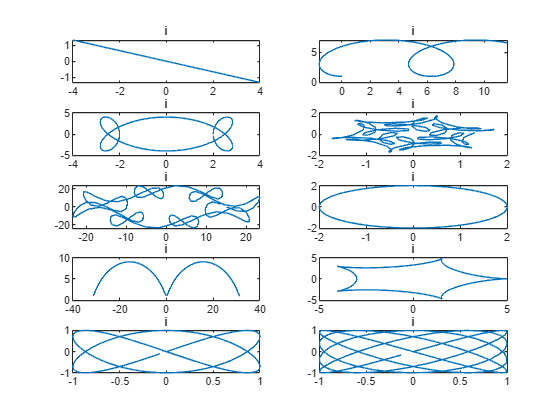


for i=1:10
    x=vec_x(i);
    y=vec_y(i);
    ti=vec_ti(i);
    tf=vec_tf(i);

    tv= ti: 0.05: tf;
   
    xf = (subs(x, t, tv));
    yf = (subs(y, t, tv));
    
    subplot(5,2,i)
    plot(xf,yf);

end
hold off